# REPRESENTACIÓN DE PROPIEDADES DE SOFA

## OBTENCIÓN DE DATOS DE SOFA

% Cargamos los datos desde un archivo dado que el tiempo de simulación es
% muy alto
% load("matlab.mat");

% Desglosamos los valores en sus respectivas componentes
[vector_tiempo_18_5,posicion_nodo_0_dcha_18_5,posicion_nodo_28_central_18_5,posicion_nodo_56_izq_18_5] = readvars('properties_0-28-56_x_18.5.txt');
[vector_tiempo_19,posicion_nodo_0_dcha_19,posicion_nodo_28_central_19,posicion_nodo_56_izq_19] = readvars('properties_0-28-56_x_19.txt');
[vector_tiempo_19_5,posicion_nodo_0_dcha_19_5,posicion_nodo_28_central_19_5,posicion_nodo_56_izq_19_5] = readvars('properties_0-28-56_x_19.5.txt');
[vector_tiempo_19_8,posicion_nodo_0_dcha_19_8,posicion_nodo_28_central_19_8,posicion_nodo_56_izq_19_8] = readvars('properties_0-28-56_x_19.8.txt');
[vector_tiempo_20,posicion_nodo_0_dcha_20,posicion_nodo_28_central_20,posicion_nodo_56_izq_20] = readvars('properties_0-28-56_x_20.txt');
[vector_tiempo_20_2,posicion_nodo_0_dcha_20_2,posicion_nodo_28_central_20_2,posicion_nodo_56_izq_20_2] = readvars('properties_0-28-56_x_20.2.txt');
[vector_tiempo_20_4,posicion_nodo_0_dcha_20_4,posicion_nodo_28_central_20_4,posicion_nodo_56_izq_20_4] = readvars('properties_0-28-56_x_20.4.txt');
[vector_tiempo_20_5,posicion_nodo_0_dcha_20_5,posicion_nodo_28_central_20_5,posicion_nodo_56_izq_20_5] = readvars('properties_0-28-56_x_20.5.txt');
[vector_tiempo_21,posicion_nodo_0_dcha_21,posicion_nodo_28_central_21,posicion_nodo_56_izq_21] = readvars('properties_0-28-56_x_21.txt');
[vector_tiempo_21_5,posicion_nodo_0_dcha_21_5,posicion_nodo_28_central_21_5,posicion_nodo_56_izq_21_5] = readvars('properties_0-28-56_x_21.5.txt');

 % Expresion que ayuda a dividir la celda cada que encontramos un espacio en el vector
expression = ' ';

% Dividimos la cadena en la misma variable pero con celdas separadas según
% hemos indicado en la variable expresión. Es decir que ashora por cada
% fila tendremos a su vez una celda dividida en 7 celdas más pequeñas
posicion_nodo_0_dcha_split_18_5 = regexp(posicion_nodo_0_dcha_18_5,expression,'split');
posicion_nodo_28_central_split_18_5 = regexp(posicion_nodo_28_central_18_5,expression,'split');
posicion_nodo_56_izq_split_18_5 = regexp(posicion_nodo_56_izq_18_5,expression,'split');

posicion_nodo_0_dcha_split_19 = regexp(posicion_nodo_0_dcha_19,expression,'split');
posicion_nodo_28_central_split_19 = regexp(posicion_nodo_28_central_19,expression,'split');
posicion_nodo_56_izq_split_19 = regexp(posicion_nodo_56_izq_19,expression,'split');

posicion_nodo_0_dcha_split_19_5 = regexp(posicion_nodo_0_dcha_19_5,expression,'split');
posicion_nodo_28_central_split_19_5 = regexp(posicion_nodo_28_central_19_5,expression,'split');
posicion_nodo_56_izq_split_19_5 = regexp(posicion_nodo_56_izq_19_5,expression,'split');

posicion_nodo_0_dcha_split_19_8 = regexp(posicion_nodo_0_dcha_19_8,expression,'split');
posicion_nodo_28_central_split_19_8 = regexp(posicion_nodo_28_central_19_8,expression,'split');
posicion_nodo_56_izq_split_19_8 = regexp(posicion_nodo_56_izq_19_8,expression,'split');

posicion_nodo_0_dcha_split_20 = regexp(posicion_nodo_0_dcha_20,expression,'split');
posicion_nodo_28_central_split_20 = regexp(posicion_nodo_28_central_20,expression,'split');
posicion_nodo_56_izq_split_20 = regexp(posicion_nodo_56_izq_20,expression,'split');

posicion_nodo_0_dcha_split_20_2 = regexp(posicion_nodo_0_dcha_20_2,expression,'split');
posicion_nodo_28_central_split_20_2 = regexp(posicion_nodo_28_central_20_2,expression,'split');
posicion_nodo_56_izq_split_20_2 = regexp(posicion_nodo_56_izq_20_2,expression,'split');

posicion_nodo_0_dcha_split_20_4 = regexp(posicion_nodo_0_dcha_20_4,expression,'split');
posicion_nodo_28_central_split_20_4 = regexp(posicion_nodo_28_central_20_4,expression,'split');
posicion_nodo_56_izq_split_20_4 = regexp(posicion_nodo_56_izq_20_4,expression,'split');

posicion_nodo_0_dcha_split_20_5 = regexp(posicion_nodo_0_dcha_20_5,expression,'split');
posicion_nodo_28_central_split_20_5 = regexp(posicion_nodo_28_central_20_5,expression,'split');
posicion_nodo_56_izq_split_20_5 = regexp(posicion_nodo_56_izq_20_5,expression,'split');

posicion_nodo_0_dcha_split_21 = regexp(posicion_nodo_0_dcha_21,expression,'split');
posicion_nodo_28_central_split_21 = regexp(posicion_nodo_28_central_21,expression,'split');
posicion_nodo_56_izq_split_21 = regexp(posicion_nodo_56_izq_21,expression,'split');

posicion_nodo_0_dcha_split_21_5 = regexp(posicion_nodo_0_dcha_21_5,expression,'split');
posicion_nodo_28_central_split_21_5 = regexp(posicion_nodo_28_central_21_5,expression,'split');
posicion_nodo_56_izq_split_21_5 = regexp(posicion_nodo_56_izq_21_5,expression,'split');

% Recolectamos los datos y los metemos en una matriz
for i=1:length(posicion_nodo_0_dcha_split_18_5)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_18_5_ = posicion_nodo_0_dcha_split_18_5{i,1};
    posicion_nodo_28_central_split_18_5_ = posicion_nodo_28_central_split_18_5{i,1};
    posicion_nodo_56_izq_split_18_5_ = posicion_nodo_56_izq_split_18_5{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_18_5_)
        
        posicion_nodo_0_dcha_split_num_18_5 = cell2mat(posicion_nodo_0_dcha_split_18_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_18_5 = cell2mat(posicion_nodo_28_central_split_18_5_(1,j));
        posicion_nodo_56_izq_split_num_18_5 = cell2mat(posicion_nodo_56_izq_split_18_5_(1,j));
        
        posiciones_nodo_0_18_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_18_5);
        posiciones_nodo_28_18_5(i,j) = str2double(posicion_nodo_28_central_split_num_18_5);
        posiciones_nodo_56_18_5(i,j) = str2double(posicion_nodo_56_izq_split_num_18_5);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19)
    
    posicion_nodo_0_dcha_split_19_ = posicion_nodo_0_dcha_split_19{i,1};
    posicion_nodo_28_central_split_19_ = posicion_nodo_28_central_split_19{i,1};
    posicion_nodo_56_izq_split_19_ = posicion_nodo_56_izq_split_19{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_19_)
        
        posicion_nodo_0_dcha_split_num_19 = cell2mat(posicion_nodo_0_dcha_split_19_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_19 = cell2mat(posicion_nodo_28_central_split_19_(1,j));
        posicion_nodo_56_izq_split_num_19 = cell2mat(posicion_nodo_56_izq_split_19_(1,j));
        
        posiciones_nodo_0_19(i,j) = str2double(posicion_nodo_0_dcha_split_num_19);
        posiciones_nodo_28_19(i,j) = str2double(posicion_nodo_28_central_split_num_19);
        posiciones_nodo_56_19(i,j) = str2double(posicion_nodo_56_izq_split_num_19);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19_5)
    
    posicion_nodo_0_dcha_split_19_5_ = posicion_nodo_0_dcha_split_19_5{i,1};
    posicion_nodo_28_central_split_19_5_ = posicion_nodo_28_central_split_19_5{i,1};
    posicion_nodo_56_izq_split_19_5_ = posicion_nodo_56_izq_split_19_5{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_19_5_)
        
        posicion_nodo_0_dcha_split_num_19_5 = cell2mat(posicion_nodo_0_dcha_split_19_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_19_5 = cell2mat(posicion_nodo_28_central_split_19_5_(1,j));
        posicion_nodo_56_izq_split_num_19_5 = cell2mat(posicion_nodo_56_izq_split_19_5_(1,j));
        
        posiciones_nodo_0_19_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_19_5);
        posiciones_nodo_28_19_5(i,j) = str2double(posicion_nodo_28_central_split_num_19_5);
        posiciones_nodo_56_19_5(i,j) = str2double(posicion_nodo_56_izq_split_num_19_5);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19_8)
    
    posicion_nodo_0_dcha_split_19_8_ = posicion_nodo_0_dcha_split_19_8{i,1};
    posicion_nodo_28_central_split_19_8_ = posicion_nodo_28_central_split_19_8{i,1};
    posicion_nodo_56_izq_split_19_8_ = posicion_nodo_56_izq_split_19_8{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_19_8_)
        
        posicion_nodo_0_dcha_split_num_19_8 = cell2mat(posicion_nodo_0_dcha_split_19_8_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_19_8 = cell2mat(posicion_nodo_28_central_split_19_8_(1,j));
        posicion_nodo_56_izq_split_num_19_8 = cell2mat(posicion_nodo_56_izq_split_19_8_(1,j));
        
        posiciones_nodo_0_19_8(i,j) = str2double(posicion_nodo_0_dcha_split_num_19_8);
        posiciones_nodo_28_19_8(i,j) = str2double(posicion_nodo_28_central_split_num_19_8);
        posiciones_nodo_56_19_8(i,j) = str2double(posicion_nodo_56_izq_split_num_19_8);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_2)
    
    posicion_nodo_0_dcha_split_20_2_ = posicion_nodo_0_dcha_split_20_2{i,1};
    posicion_nodo_28_central_split_20_2_ = posicion_nodo_28_central_split_20_2{i,1};
    posicion_nodo_56_izq_split_20_2_ = posicion_nodo_56_izq_split_20_2{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_20_2_)
        
        posicion_nodo_0_dcha_split_num_20_2 = cell2mat(posicion_nodo_0_dcha_split_20_2_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_20_2 = cell2mat(posicion_nodo_28_central_split_20_2_(1,j));
        posicion_nodo_56_izq_split_num_20_2 = cell2mat(posicion_nodo_56_izq_split_20_2_(1,j));
        
        posiciones_nodo_0_20_2(i,j) = str2double(posicion_nodo_0_dcha_split_num_20_2);
        posiciones_nodo_28_20_2(i,j) = str2double(posicion_nodo_28_central_split_num_20_2);
        posiciones_nodo_56_20_2(i,j) = str2double(posicion_nodo_56_izq_split_num_20_2);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20)
    
    posicion_nodo_0_dcha_split_20_ = posicion_nodo_0_dcha_split_20{i,1};
    posicion_nodo_28_central_split_20_ = posicion_nodo_28_central_split_20{i,1};
    posicion_nodo_56_izq_split_20_ = posicion_nodo_56_izq_split_20{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_20_)
        
        posicion_nodo_0_dcha_split_num_20 = cell2mat(posicion_nodo_0_dcha_split_20_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_20 = cell2mat(posicion_nodo_28_central_split_20_(1,j));
        posicion_nodo_56_izq_split_num_20 = cell2mat(posicion_nodo_56_izq_split_20_(1,j));
        
        posiciones_nodo_0_20(i,j) = str2double(posicion_nodo_0_dcha_split_num_20);
        posiciones_nodo_28_20(i,j) = str2double(posicion_nodo_28_central_split_num_20);
        posiciones_nodo_56_20(i,j) = str2double(posicion_nodo_56_izq_split_num_20);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_4)
    
    posicion_nodo_0_dcha_split_20_4_ = posicion_nodo_0_dcha_split_20_4{i,1};
    posicion_nodo_28_central_split_20_4_ = posicion_nodo_28_central_split_20_4{i,1};
    posicion_nodo_56_izq_split_20_4_ = posicion_nodo_56_izq_split_20_4{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_20_4_)
        
        posicion_nodo_0_dcha_split_num_20_4 = cell2mat(posicion_nodo_0_dcha_split_20_4_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_20_4 = cell2mat(posicion_nodo_28_central_split_20_4_(1,j));
        posicion_nodo_56_izq_split_num_20_4 = cell2mat(posicion_nodo_56_izq_split_20_4_(1,j));
        
        posiciones_nodo_0_20_4(i,j) = str2double(posicion_nodo_0_dcha_split_num_20_4);
        posiciones_nodo_28_20_4(i,j) = str2double(posicion_nodo_28_central_split_num_20_4);
        posiciones_nodo_56_20_4(i,j) = str2double(posicion_nodo_56_izq_split_num_20_4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_5)
    
    posicion_nodo_0_dcha_split_20_5_ = posicion_nodo_0_dcha_split_20_5{i,1};
    posicion_nodo_28_central_split_20_5_ = posicion_nodo_28_central_split_20_5{i,1};
    posicion_nodo_56_izq_split_20_5_ = posicion_nodo_56_izq_split_20_5{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_20_5_)
        
        posicion_nodo_0_dcha_split_num_20_5 = cell2mat(posicion_nodo_0_dcha_split_20_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_20_5 = cell2mat(posicion_nodo_28_central_split_20_5_(1,j));
        posicion_nodo_56_izq_split_num_20_5 = cell2mat(posicion_nodo_56_izq_split_20_5_(1,j));
        
        posiciones_nodo_0_20_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_20_5);
        posiciones_nodo_28_20_5(i,j) = str2double(posicion_nodo_28_central_split_num_20_5);
        posiciones_nodo_56_20_5(i,j) = str2double(posicion_nodo_56_izq_split_num_20_5);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_21)
    
    posicion_nodo_0_dcha_split_21_ = posicion_nodo_0_dcha_split_21{i,1};
    posicion_nodo_28_central_split_21_ = posicion_nodo_28_central_split_21{i,1};
    posicion_nodo_56_izq_split_21_ = posicion_nodo_56_izq_split_21{i,1};
    
    for j=1:length(posicion_nodo_0_dcha_split_21_)
        
        posicion_nodo_0_dcha_split_num_21 = cell2mat(posicion_nodo_0_dcha_split_21_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_21 = cell2mat(posicion_nodo_28_central_split_21_(1,j));
        posicion_nodo_56_izq_split_num_21 = cell2mat(posicion_nodo_56_izq_split_21_(1,j));
        
        posiciones_nodo_0_21(i,j) = str2double(posicion_nodo_0_dcha_split_num_21);
        posiciones_nodo_28_21(i,j) = str2double(posicion_nodo_28_central_split_num_21);
        posiciones_nodo_56_21(i,j) = str2double(posicion_nodo_56_izq_split_num_21);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_21_5)
    
    posicion_nodo_0_dcha_split_21_5_ = posicion_nodo_0_dcha_split_21_5{i,1};
    posicion_nodo_28_central_split_21_5_ = posicion_nodo_28_central_split_21_5{i,1};
    posicion_nodo_56_izq_split_21_5_ = posicion_nodo_56_izq_split_21_5{i,1};

    for j=1:length(posicion_nodo_0_dcha_split_21_5_)
        
        posicion_nodo_0_dcha_split_num_21_5 = cell2mat(posicion_nodo_0_dcha_split_21_5_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num_21_5 = cell2mat(posicion_nodo_28_central_split_21_5_(1,j));
        posicion_nodo_56_izq_split_num_21_5 = cell2mat(posicion_nodo_56_izq_split_21_5_(1,j));
        
        posiciones_nodo_0_21_5(i,j) = str2double(posicion_nodo_0_dcha_split_num_21_5);
        posiciones_nodo_28_21_5(i,j) = str2double(posicion_nodo_28_central_split_num_21_5);
        posiciones_nodo_56_21_5(i,j) = str2double(posicion_nodo_56_izq_split_num_21_5);
    end
end

## HALLAMOS EL VALOR MÁXIMO Y MÍNIMO DE DESPLAZAMIENTO

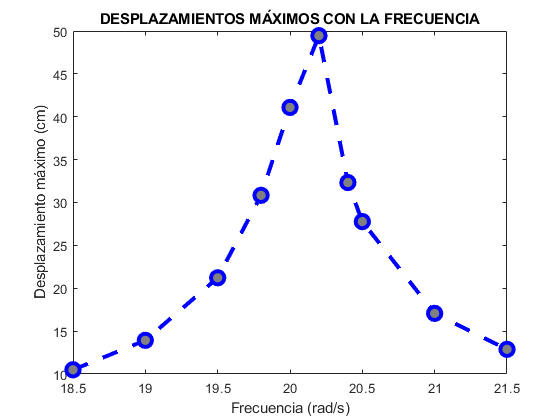

% Todas las posiciones están en metros, salvo la última sentencia

% Concatenamos los vectores del tiempo y las posiciones recogidas de los
% nodos estudiados para detectar dónde se encuentra el máximo y el mínimo
posicion_0_18_5_ = [vector_tiempo_18_5 posiciones_nodo_0_18_5];
posicion_28_18_5_ = [vector_tiempo_18_5 posiciones_nodo_28_18_5];
posicion_56_18_5_ = [vector_tiempo_18_5 posiciones_nodo_56_18_5];

posicion_0_19_ = [vector_tiempo_19 posiciones_nodo_0_19];
posicion_28_19_ = [vector_tiempo_19 posiciones_nodo_28_19];
posicion_56_19_ = [vector_tiempo_19 posiciones_nodo_56_19];

posicion_0_19_5_ = [vector_tiempo_19_5 posiciones_nodo_0_19_5];
posicion_28_19_5_ = [vector_tiempo_19_5 posiciones_nodo_28_19_5];
posicion_56_19_5_ = [vector_tiempo_19_5 posiciones_nodo_56_19_5];

posicion_0_19_8_ = [vector_tiempo_19_8 posiciones_nodo_0_19_8];
posicion_28_19_8_ = [vector_tiempo_19_8 posiciones_nodo_28_19_8];
posicion_56_19_8_ = [vector_tiempo_19_8 posiciones_nodo_56_19_8];

posicion_0_20_ = [vector_tiempo_20 posiciones_nodo_0_20];
posicion_28_20_ = [vector_tiempo_20 posiciones_nodo_28_20];
posicion_56_20_ = [vector_tiempo_20 posiciones_nodo_56_20];

posicion_0_20_2_ = [vector_tiempo_20_2 posiciones_nodo_0_20_2];
posicion_28_20_2_ = [vector_tiempo_20_2 posiciones_nodo_28_20_2];
posicion_56_20_2_ = [vector_tiempo_20_2 posiciones_nodo_56_20_2];

posicion_0_20_4_ = [vector_tiempo_20_4 posiciones_nodo_0_20_4];
posicion_28_20_4_ = [vector_tiempo_20_4 posiciones_nodo_28_20_4];
posicion_56_20_4_ = [vector_tiempo_20_4 posiciones_nodo_56_20_4];

posicion_0_20_5_ = [vector_tiempo_20_5 posiciones_nodo_0_20_5];
posicion_28_20_5_ = [vector_tiempo_20_5 posiciones_nodo_28_20_5];
posicion_56_20_5_ = [vector_tiempo_20_5 posiciones_nodo_56_20_5];

posicion_0_21_ = [vector_tiempo_21 posiciones_nodo_0_21];
posicion_28_21_ = [vector_tiempo_21 posiciones_nodo_28_21];
posicion_56_21_ = [vector_tiempo_21 posiciones_nodo_56_21];

posicion_0_21_5_ = [vector_tiempo_21_5 posiciones_nodo_0_21_5];
posicion_28_21_5_ = [vector_tiempo_21_5 posiciones_nodo_28_21_5];
posicion_56_21_5_ = [vector_tiempo_21_5 posiciones_nodo_56_21_5];

% Obtenemos el máximo y mínimo de los tres nodos
M_0_18_5 = max(posicion_0_18_5_(:,4));
m_0_18_5 = min(posicion_0_18_5_(:,4));
M_28_18_5 = max(posicion_28_18_5_(:,4));
m_28_18_5 = min(posicion_28_18_5_(:,4));
M_56_18_5 = max(posicion_56_18_5_(:,4));
m_56_18_5 = min(posicion_56_18_5_(:,4));

M_0_19 = max(posicion_0_19_(:,4));
m_0_19 = min(posicion_0_19_(:,4));
M_28_19 = max(posicion_28_19_(:,4));
m_28_19 = min(posicion_28_19_(:,4));
M_56_19 = max(posicion_56_19_(:,4));
m_56_19 = min(posicion_56_19_(:,4));

M_0_19_5 = max(posicion_0_19_5_(:,4));
m_0_19_5 = min(posicion_0_19_5_(:,4));
M_28_19_5 = max(posicion_28_19_5_(:,4));
m_28_19_5 = min(posicion_28_19_5_(:,4));
M_56_19_5 = max(posicion_56_19_5_(:,4));
m_56_19_5 = min(posicion_56_19_5_(:,4));

M_0_19_8 = max(posicion_0_19_8_(:,4));
m_0_19_8 = min(posicion_0_19_8_(:,4));
M_28_19_8 = max(posicion_28_19_8_(:,4));
m_28_19_8 = min(posicion_28_19_8_(:,4));
M_56_19_8 = max(posicion_56_19_8_(:,4));
m_56_19_8 = min(posicion_56_19_8_(:,4));

M_0_20 = max(posicion_0_20_(:,4));
m_0_20 = min(posicion_0_20_(:,4));
M_28_20 = max(posicion_28_20_(:,4));
m_28_20 = min(posicion_28_20_(:,4));
M_56_20 = max(posicion_56_20_(:,4));
m_56_20 = min(posicion_56_20_(:,4));

M_0_20_2 = max(posicion_0_20_2_(:,4));
m_0_20_2 = min(posicion_0_20_2_(:,4));
M_28_20_2 = max(posicion_28_20_2_(:,4));
m_28_20_2 = min(posicion_28_20_2_(:,4));
M_56_20_2 = max(posicion_56_20_2_(:,4));
m_56_20_2 = min(posicion_56_20_2_(:,4));

M_0_20_4 = max(posicion_0_20_4_(:,4));
m_0_20_4 = min(posicion_0_20_4_(:,4));
M_28_20_4 = max(posicion_28_20_4_(:,4));
m_28_20_4 = min(posicion_28_20_4_(:,4));
M_56_20_4 = max(posicion_56_20_4_(:,4));
m_56_20_4 = min(posicion_56_20_4_(:,4));

M_0_20_5 = max(posicion_0_20_5_(:,4));
m_0_20_5 = min(posicion_0_20_5_(:,4));
M_28_20_5 = max(posicion_28_20_5_(:,4));
m_28_20_5 = min(posicion_28_20_5_(:,4));
M_56_20_5 = max(posicion_56_20_5_(:,4));
m_56_20_5 = min(posicion_56_20_5_(:,4));

M_0_21 = max(posicion_0_21_(:,4));
m_0_21 = min(posicion_0_21_(:,4));
M_28_21 = max(posicion_28_21_(:,4));
m_28_21 = min(posicion_28_21_(:,4));
M_56_21 = max(posicion_56_21_(:,4));
m_56_21 = min(posicion_56_21_(:,4));

M_0_21_5 = max(posicion_0_21_5_(:,4));
m_0_21_5 = min(posicion_0_21_5_(:,4));
M_28_21_5 = max(posicion_28_21_5_(:,4));
m_28_21_5 = min(posicion_28_21_5_(:,4));
M_56_21_5 = max(posicion_56_21_5_(:,4));
m_56_21_5 = min(posicion_56_21_5_(:,4));

% Detectamos el tiempo para el cual se ha alcanzado el mínimo y lo
% guardamos en una variable auxiliar
for i=1:length(posicion_nodo_0_dcha_split_18_5)
    if (m_0_18_5==posicion_0_18_5_(i,4))

        tiempo_0_18_5 = posicion_0_18_5_(i,1);
    end
    if (m_56_18_5==posicion_56_18_5_(i,4))

        tiempo_56_18_5 = posicion_56_18_5_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19)
    if (m_0_19==posicion_0_19_(i,4))

        tiempo_0_19 = posicion_0_19_(i,1);
    end
    if (m_56_19==posicion_56_19_(i,4))

        tiempo_56_19 = posicion_56_19_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19_5)
    if (m_0_19_5==posicion_0_19_5_(i,4))

        tiempo_0_19_5 = posicion_0_19_5_(i,1);
    end
    if (m_56_19_5==posicion_56_19_5_(i,4))

        tiempo_56_19_5 = posicion_56_19_5_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19_8)
    if (m_0_19_8==posicion_0_19_8_(i,4))

        tiempo_0_19_8 = posicion_0_19_8_(i,1);
    end
    if (m_56_19_8==posicion_56_19_8_(i,4))

        tiempo_56_19_8 = posicion_56_19_8_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20)
    if (m_0_20==posicion_0_20_(i,4))

        tiempo_0_20 = posicion_0_20_(i,1);
    end
    if (m_56_20==posicion_56_20_(i,4))

        tiempo_56_20 = posicion_56_20_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_2)
    if (m_0_20_2==posicion_0_20_2_(i,4))

        tiempo_0_20_2 = posicion_0_20_2_(i,1);
    end
    if (m_56_20_2==posicion_56_20_2_(i,4))

        tiempo_56_20_2 = posicion_56_20_2_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_4)
    if (m_0_20_4==posicion_0_20_4_(i,4))

        tiempo_0_20_4 = posicion_0_20_4_(i,1);
    end
    if (m_56_20_4==posicion_56_20_4_(i,4))

        tiempo_56_20_4 = posicion_56_20_4_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_5)
    if (m_0_20_5==posicion_0_20_5_(i,4))

        tiempo_0_20_5 = posicion_0_20_5_(i,1);
    end
    if (m_56_20_5==posicion_56_20_5_(i,4))

        tiempo_56_20_5 = posicion_56_20_5_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_21)
    if (m_0_21==posicion_0_21_(i,4))

        tiempo_0_21 = posicion_0_21_(i,1);
    end
    if (m_56_21==posicion_56_21_(i,4))

        tiempo_56_21 = posicion_56_21_(i,1);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_21_5)
    if (m_0_21_5==posicion_0_21_5_(i,4))

        tiempo_0_21_5 = posicion_0_21_5_(i,1);
    end
    if (m_56_21_5==posicion_56_21_5_(i,4))

        tiempo_56_21_5 = posicion_56_21_5_(i,1);
    end
end

% Para dicho tiempo, cogemos la posición del nodo central
for i=1:length(posicion_nodo_0_dcha_split_18_5)
    if (tiempo_0_18_5==posicion_28_18_5_(i,1))

        posicion_resta_18_5 = posicion_28_18_5_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19)
    if (tiempo_0_19==posicion_28_19_(i,1))

        posicion_resta_19 = posicion_28_19_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19_5)
    if (tiempo_0_19_5==posicion_28_19_5_(i,1))

        posicion_resta_19_5 = posicion_28_19_5_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_19_8)
    if (tiempo_0_19_8==posicion_28_19_8_(i,1))

        posicion_resta_19_8 = posicion_28_19_8_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20)
    if (tiempo_0_20==posicion_28_20_(i,1))

        posicion_resta_20 = posicion_28_20_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_2)
    if (tiempo_0_20_2==posicion_28_20_2_(i,1))

        posicion_resta_20_2 = posicion_28_20_2_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_4)
    if (tiempo_0_20_4==posicion_28_20_4_(i,1))

        posicion_resta_20_4 = posicion_28_20_4_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_20_5)
    if (tiempo_0_20_5==posicion_28_20_5_(i,1))

        posicion_resta_20_5 = posicion_28_20_5_(i,4);
    end
end

for i=1:length(posicion_nodo_0_dcha_split_21)
    if (tiempo_0_21==posicion_28_21_(i,1))

        posicion_resta_21 = posicion_28_21_(i,4);
    end
end
for i=1:length(posicion_nodo_0_dcha_split_21_5)
    if (tiempo_0_21_5==posicion_28_21_5_(i,1))

        posicion_resta_21_5 = posicion_28_21_5_(i,4);
    end
end

% Una vez con dicha posición del nodo central, podemos obtener de una
% manera más precisa cuál es el desplazamiento máximo, medido como la
% distancia que hay del nodo central a ambos puntos extremos de la barra
% Unidades en cm
desplazamiento_real_derecho_18_5 = (abs(m_0_18_5) + posicion_resta_18_5)*100;
desplazamiento_real_izquierdo_18_5 = (abs(m_56_18_5) + posicion_resta_18_5)*100;
desplazamiento_18_5 = [desplazamiento_real_derecho_18_5 desplazamiento_real_izquierdo_18_5];
desplazamiento_medio_18_5 = mean(desplazamiento_18_5);

desplazamiento_real_derecho_19 = (abs(m_0_19) + posicion_resta_19)*100;
desplazamiento_real_izquierdo_19 = (abs(m_56_19) + posicion_resta_19)*100;
desplazamiento_19 = [desplazamiento_real_derecho_19 desplazamiento_real_izquierdo_19];
desplazamiento_medio_19 = mean(desplazamiento_19);

desplazamiento_real_derecho_19_5 = (abs(m_0_19_5) + posicion_resta_19_5)*100;
desplazamiento_real_izquierdo_19_5 = (abs(m_56_19_5) + posicion_resta_19_5)*100;
desplazamiento_19_5 = [desplazamiento_real_derecho_19_5 desplazamiento_real_izquierdo_19_5];
desplazamiento_medio_19_5 = mean(desplazamiento_19_5);

desplazamiento_real_derecho_19_8 = (abs(m_0_19_8) + posicion_resta_19_8)*100;
desplazamiento_real_izquierdo_19_8 = (abs(m_56_19_8) + posicion_resta_19_8)*100;
desplazamiento_19_8 = [desplazamiento_real_derecho_19_8 desplazamiento_real_izquierdo_19_8];
desplazamiento_medio_19_8 = mean(desplazamiento_19_8);

desplazamiento_real_derecho_20 = (abs(m_0_20) + posicion_resta_20)*100;
desplazamiento_real_izquierdo_20 = (abs(m_56_20) + posicion_resta_20)*100;
desplazamiento_20 = [desplazamiento_real_derecho_20 desplazamiento_real_izquierdo_20];
desplazamiento_medio_20 = mean(desplazamiento_20);

desplazamiento_real_derecho_20_2 = (abs(m_0_20_2) + posicion_resta_20_2)*100;
desplazamiento_real_izquierdo_20_2 = (abs(m_56_20_2) + posicion_resta_20_2)*100;
desplazamiento_20_2 = [desplazamiento_real_derecho_20_2 desplazamiento_real_izquierdo_20_2];
desplazamiento_medio_20_2 = mean(desplazamiento_20_2);

desplazamiento_real_derecho_20_4 = (abs(m_0_20_4) + posicion_resta_20_4)*100;
desplazamiento_real_izquierdo_20_4 = (abs(m_56_20_4) + posicion_resta_20_4)*100;
desplazamiento_20_4 = [desplazamiento_real_derecho_20_4 desplazamiento_real_izquierdo_20_4];
desplazamiento_medio_20_4 = mean(desplazamiento_20_4);

desplazamiento_real_derecho_20_5 = (abs(m_0_20_5) + posicion_resta_20_5)*100;
desplazamiento_real_izquierdo_20_5 = (abs(m_56_20_5) + posicion_resta_20_5)*100;
desplazamiento_20_5 = [desplazamiento_real_derecho_20_5 desplazamiento_real_izquierdo_20_5];
desplazamiento_medio_20_5 = mean(desplazamiento_20_5);

desplazamiento_real_derecho_21 = (abs(m_0_21) + posicion_resta_21)*100;
desplazamiento_real_izquierdo_21 = (abs(m_56_21) + posicion_resta_21)*100;
desplazamiento_21 = [desplazamiento_real_derecho_21 desplazamiento_real_izquierdo_21];
desplazamiento_medio_21 = mean(desplazamiento_21);

desplazamiento_real_derecho_21_5 = (abs(m_0_21_5) + posicion_resta_21_5)*100;
desplazamiento_real_izquierdo_21_5 = (abs(m_56_21_5) + posicion_resta_21_5)*100;
desplazamiento_21_5 = [desplazamiento_real_derecho_21_5 desplazamiento_real_izquierdo_21_5];
desplazamiento_medio_21_5 = mean(desplazamiento_21_5);

% Almacenamos el valor a mano de las frecuencias estudiadas en SOFA
frecuencias = [18.5 19 19.5 19.8 20 20.2 20.4 20.5 21 21.5];
% Almacenamos el valor de los desplazamientos obtenidos
desp = [desplazamiento_medio_18_5 desplazamiento_medio_19 desplazamiento_medio_19_5 desplazamiento_medio_19_8 desplazamiento_medio_20 desplazamiento_medio_20_2 desplazamiento_medio_20_4 desplazamiento_medio_20_5 desplazamiento_medio_21 desplazamiento_medio_21_5];

% Representamos dichos valores de desplazamientos
plot(frecuencias,desp,'--bo',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
title('Energía elástica acumulada en la barra')
xlabel('Frecuencia (rad/s)')
ylabel('Energía elástica (J)')
title('DESPLAZAMIENTOS MÁXIMOS CON LA FRECUENCIA')
xlabel('Frecuencia (rad/s)') 
ylabel('Desplazamiento máximo (cm)')

## REPRESENTACIÓN 3D DE LOS DESPLAZAMIENTOS DE LOS NODOS A LAS FRECUENCIAS ESTUDIADAS

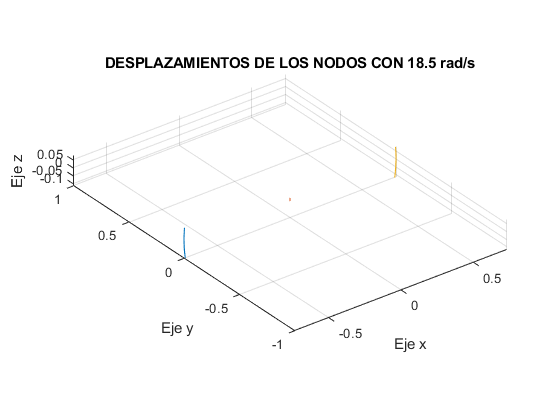

% Obtenemos una representación gráfica con los valores de X,Y y Z de los 3 nodos
% estudiados de la barra

% Realizar para cada simulatiom step para mostrar las diferencias

plot3(posiciones_nodo_0_18_5(:,1),posiciones_nodo_0_18_5(:,2),posiciones_nodo_0_18_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 18.5 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_18_5(:,1),posiciones_nodo_28_18_5(:,2),posiciones_nodo_28_18_5(:,3))
plot3(posiciones_nodo_56_18_5(:,1),posiciones_nodo_56_18_5(:,2),posiciones_nodo_56_18_5(:,3))
hold off

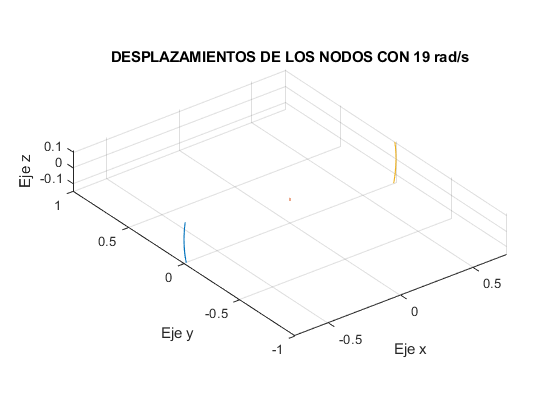


plot3(posiciones_nodo_0_19(:,1),posiciones_nodo_0_19(:,2),posiciones_nodo_0_19(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 19 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_19(:,1),posiciones_nodo_28_19(:,2),posiciones_nodo_28_19(:,3))
plot3(posiciones_nodo_56_19(:,1),posiciones_nodo_56_19(:,2),posiciones_nodo_56_19(:,3))
hold off

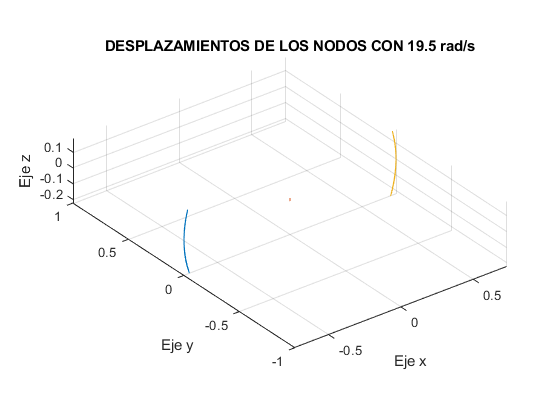


plot3(posiciones_nodo_0_19_5(:,1),posiciones_nodo_0_19_5(:,2),posiciones_nodo_0_19_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 19.5 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_19_5(:,1),posiciones_nodo_28_19_5(:,2),posiciones_nodo_28_19_5(:,3))
plot3(posiciones_nodo_56_19_5(:,1),posiciones_nodo_56_19_5(:,2),posiciones_nodo_56_19_5(:,3))
hold off

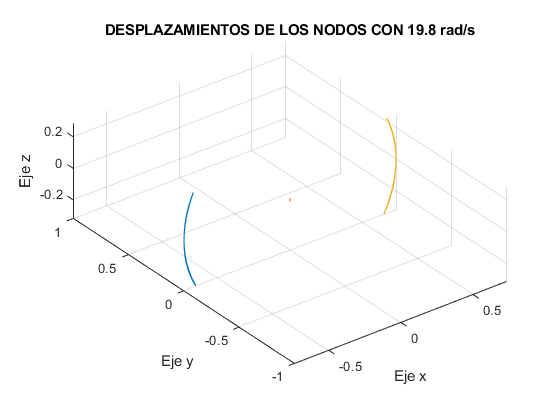


plot3(posiciones_nodo_0_19_8(:,1),posiciones_nodo_0_19_8(:,2),posiciones_nodo_0_19_8(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 19.8 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_19_8(:,1),posiciones_nodo_28_19_8(:,2),posiciones_nodo_28_19_8(:,3))
plot3(posiciones_nodo_56_19_8(:,1),posiciones_nodo_56_19_8(:,2),posiciones_nodo_56_19_8(:,3))
hold off

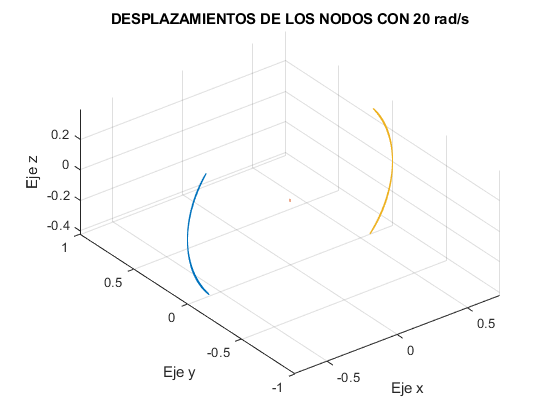


plot3(posiciones_nodo_0_20(:,1),posiciones_nodo_0_20(:,2),posiciones_nodo_0_20(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 20 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_20(:,1),posiciones_nodo_28_20(:,2),posiciones_nodo_28_20(:,3))
plot3(posiciones_nodo_56_20(:,1),posiciones_nodo_56_20(:,2),posiciones_nodo_56_20(:,3))
hold off

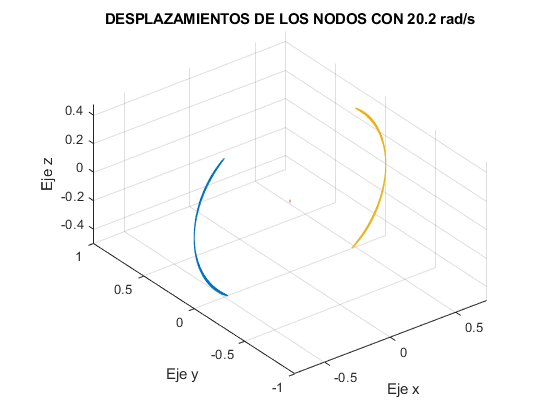


plot3(posiciones_nodo_0_20_2(:,1),posiciones_nodo_0_20_2(:,2),posiciones_nodo_0_20_2(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 20.2 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_20_2(:,1),posiciones_nodo_28_20_2(:,2),posiciones_nodo_28_20_2(:,3))
plot3(posiciones_nodo_56_20_2(:,1),posiciones_nodo_56_20_2(:,2),posiciones_nodo_56_20_2(:,3))
hold off

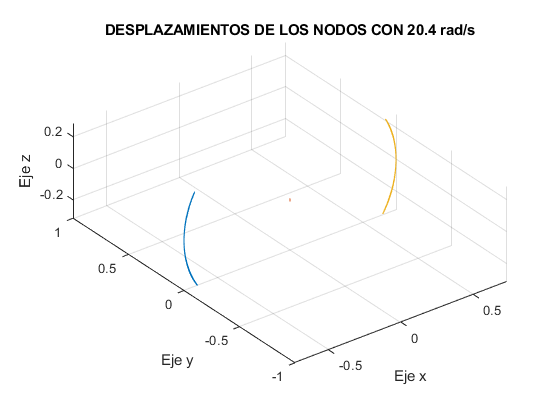


plot3(posiciones_nodo_0_20_4(:,1),posiciones_nodo_0_20_4(:,2),posiciones_nodo_0_20_4(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 20.4 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_20_4(:,1),posiciones_nodo_28_20_4(:,2),posiciones_nodo_28_20_4(:,3))
plot3(posiciones_nodo_56_20_4(:,1),posiciones_nodo_56_20_4(:,2),posiciones_nodo_56_20_4(:,3))
hold off

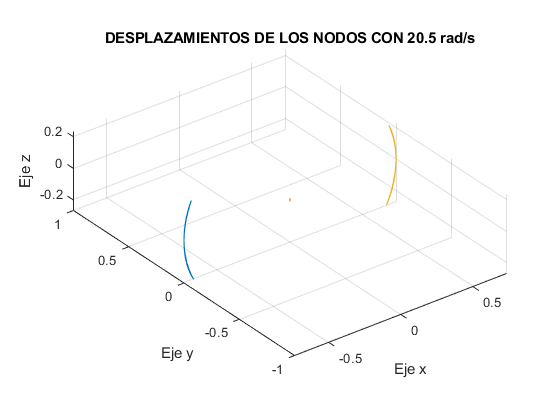


plot3(posiciones_nodo_0_20_5(:,1),posiciones_nodo_0_20_5(:,2),posiciones_nodo_0_20_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 20.5 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_20_5(:,1),posiciones_nodo_28_20_5(:,2),posiciones_nodo_28_20_5(:,3))
plot3(posiciones_nodo_56_20_5(:,1),posiciones_nodo_56_20_5(:,2),posiciones_nodo_56_20_5(:,3))
hold off

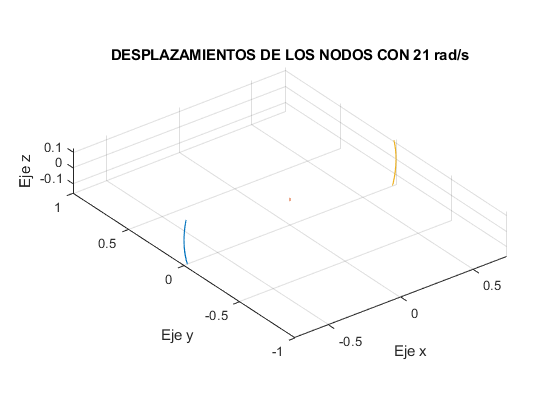


plot3(posiciones_nodo_0_21(:,1),posiciones_nodo_0_21(:,2),posiciones_nodo_0_21(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 21 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_21(:,1),posiciones_nodo_28_21(:,2),posiciones_nodo_28_21(:,3))
plot3(posiciones_nodo_56_21(:,1),posiciones_nodo_56_21(:,2),posiciones_nodo_56_21(:,3))
hold off

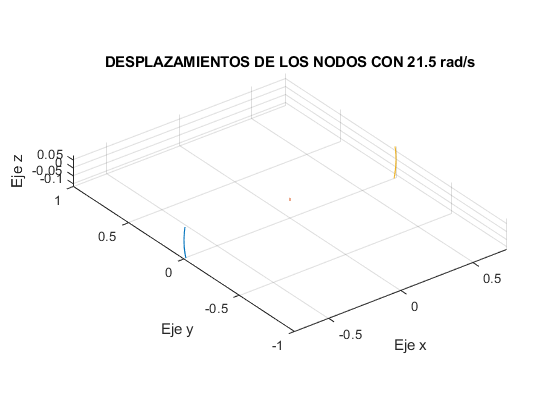


plot3(posiciones_nodo_0_21_5(:,1),posiciones_nodo_0_21_5(:,2),posiciones_nodo_0_21_5(:,3))
title('DESPLAZAMIENTOS DE LOS NODOS CON 21.5 rad/s')
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28_21_5(:,1),posiciones_nodo_28_21_5(:,2),posiciones_nodo_28_21_5(:,3))
plot3(posiciones_nodo_56_21_5(:,1),posiciones_nodo_56_21_5(:,2),posiciones_nodo_56_21_5(:,3))
hold off

## REPRESENTACIÓN DE ENERGÍA CINÉTICA PARA TODAS LAS FRECUENCIAS

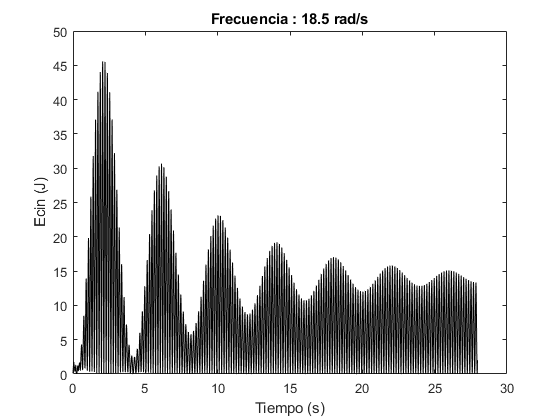

% Leemos los archivos procedentes de SOFA con los datos de energía cinética
% para las distintas frecuencias.
[vector_tiempo5,Ecin5] = readvars('Energy_wcin_18.5.txt');
[vector_tiempo1,Ecin1] = readvars('Energy_wcin_19.5.txt');
[vector_tiempo2,Ecin2] = readvars('Energy_wcin_19.txt');
[vector_tiempo6,Ecin6] = readvars('Energy_wcin_21.txt');
[vector_tiempo3,Ecin3] = readvars('Energy_wcin_20.txt');
[vector_tiempo9,Ecin9] = readvars('Energy_wcin_20.2.txt');
[vector_tiempo8,Ecin8] = readvars('Energy_wcin_20.4.txt');
[vector_tiempo4,Ecin4] = readvars('Energy_wcin_20.5.txt');
[vector_tiempo7,Ecin7] = readvars('Energy_wcin_21.5.txt');
[vector_tiempo10,Ecin10] = readvars('Energy_wcin_19.8.txt');

% Realizamos las representación de las distintas energías para cada
% frecuencia estudiada
plot(vector_tiempo5,Ecin5,'k')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 18.5 rad/s')

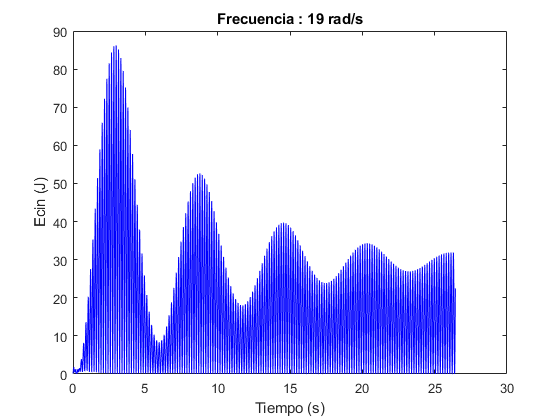

plot(vector_tiempo2,Ecin2,'b')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 19 rad/s')

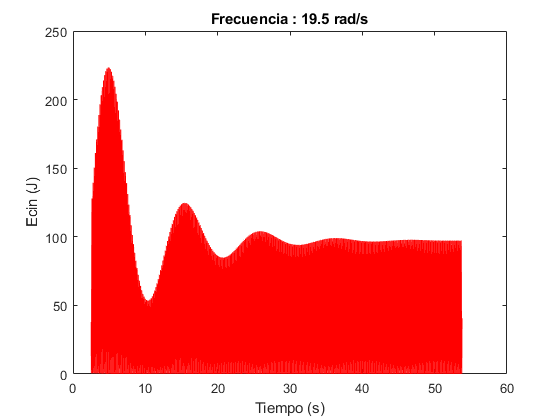

plot(vector_tiempo1,Ecin1,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 19.5 rad/s')

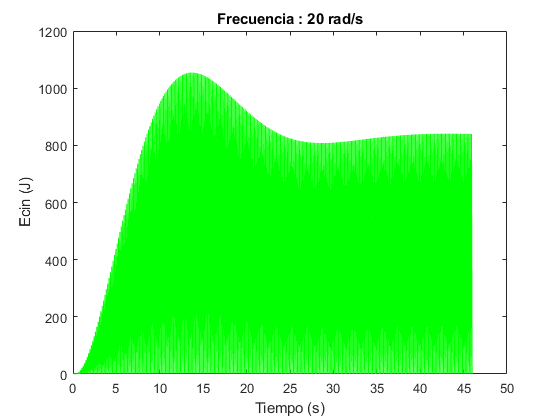

plot(vector_tiempo3,Ecin3,'g')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 20 rad/s')

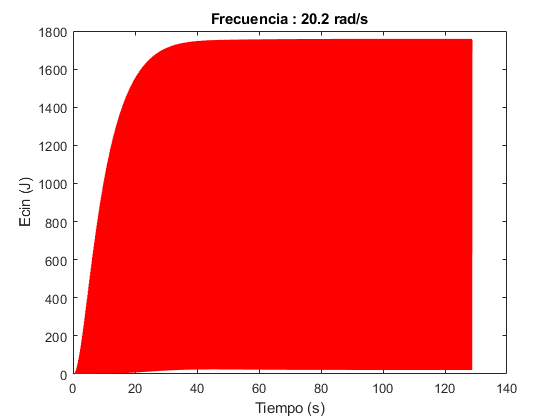

plot(vector_tiempo9,Ecin9,'r')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 20.2 rad/s')

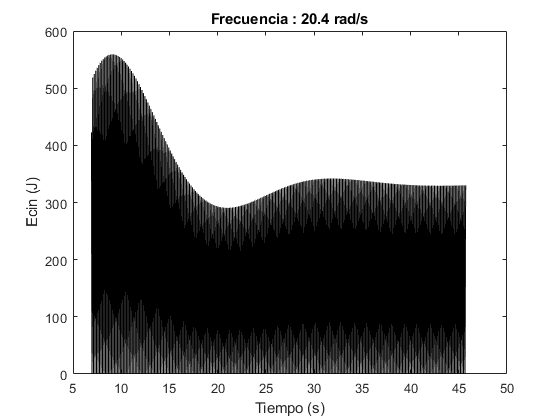

plot(vector_tiempo8,Ecin8,'k')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 20.4 rad/s')

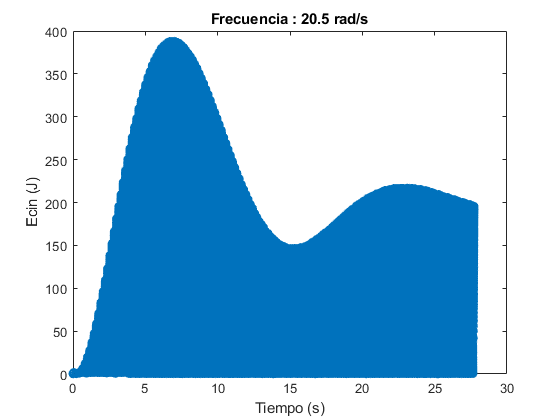

plot(vector_tiempo4,Ecin4,'o')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 20.5 rad/s')

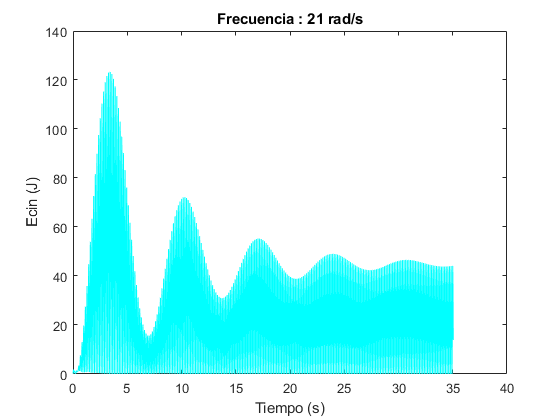

plot(vector_tiempo6,Ecin6,'c')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 21 rad/s')

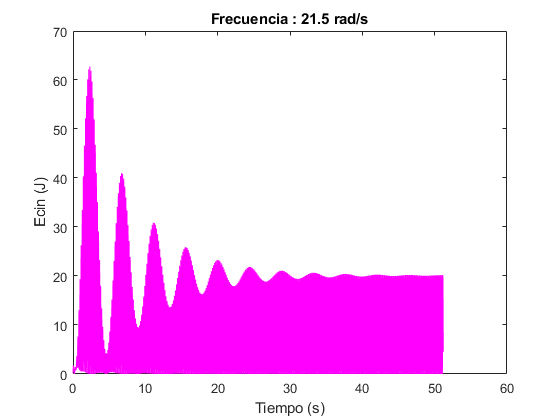

plot(vector_tiempo7,Ecin7,'m')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')
title('Frecuencia : 21.5 rad/s')

## REPRESENTACIÓN DE ENERGÍAS POTENCIALES PARA TODAS LAS FRECUENCIAS

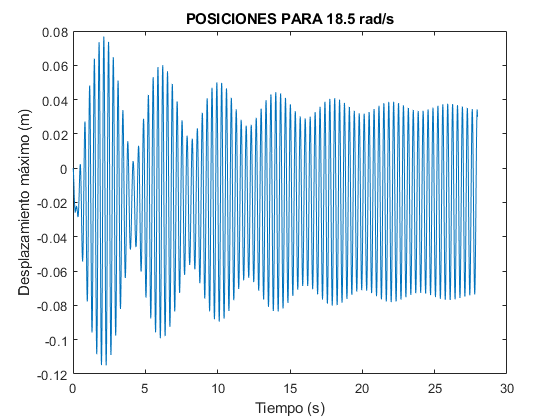

% Leemos los archivos procedentes de SOFA con los datos de las posiciones
% para las distintas frecuencias.

% Representamos primeros las posiciones en una grafica 2D
plot(vector_tiempo_18_5,posiciones_nodo_0_18_5(:,3))
title('POSICIONES PARA 18.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')

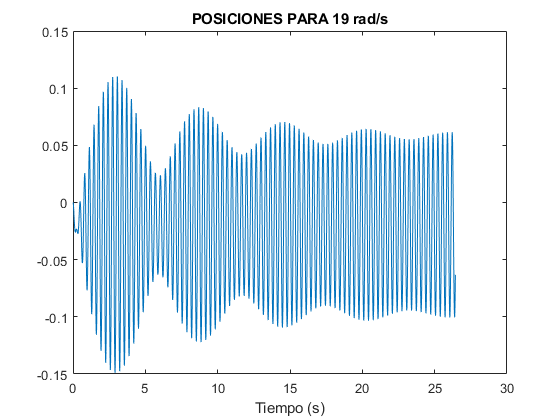


plot(vector_tiempo_19,posiciones_nodo_0_19(:,3))
title('POSICIONES PARA 19 rad/s')
xlabel('Tiempo (s)')

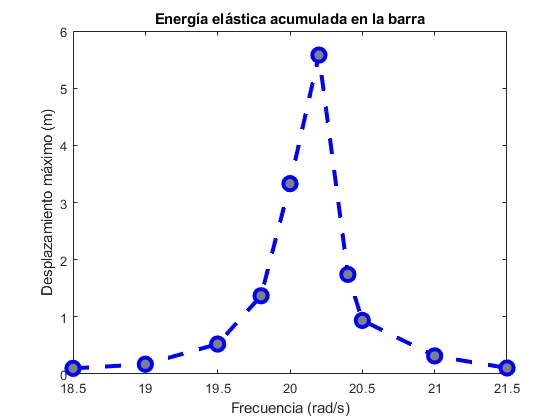

ylabel('Desplazamiento máximo (m)') 

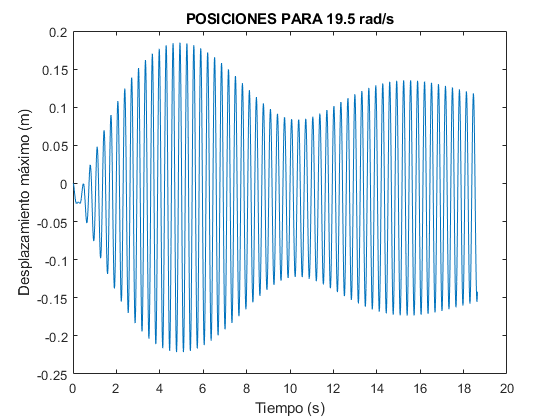


plot(vector_tiempo_19_5,posiciones_nodo_0_19_5(:,3))
title('POSICIONES PARA 19.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

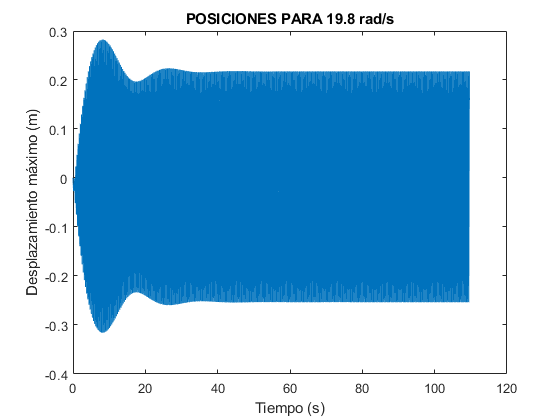


plot(vector_tiempo_19_8,posiciones_nodo_0_19_8(:,3))
title('POSICIONES PARA 19.8 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

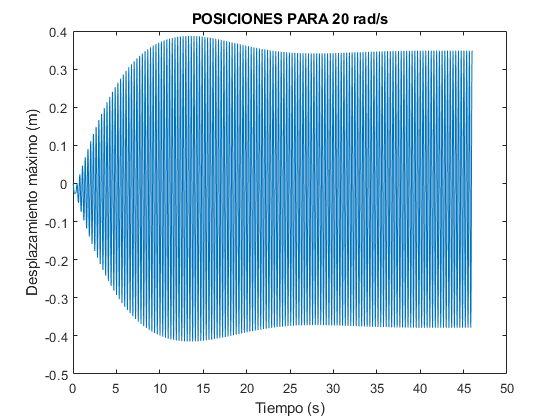


plot(vector_tiempo_20,posiciones_nodo_0_20(:,3))
title('POSICIONES PARA 20 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

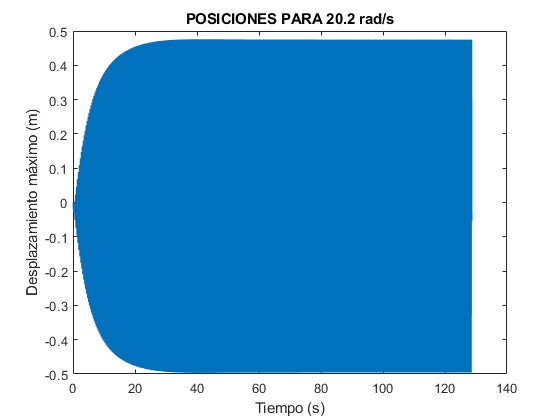


plot(vector_tiempo_20_2,posiciones_nodo_0_20_2(:,3))
title('POSICIONES PARA 20.2 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

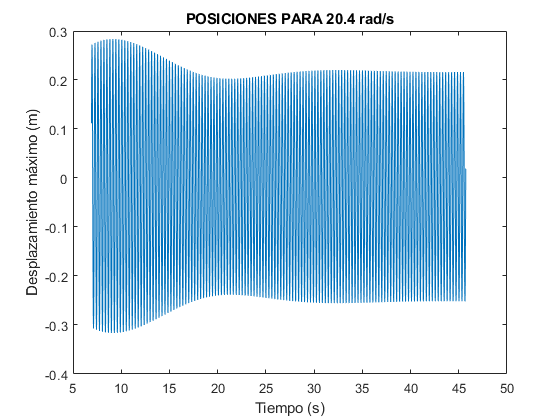


plot(vector_tiempo_20_4,posiciones_nodo_0_20_4(:,3))
title('POSICIONES PARA 20.4 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

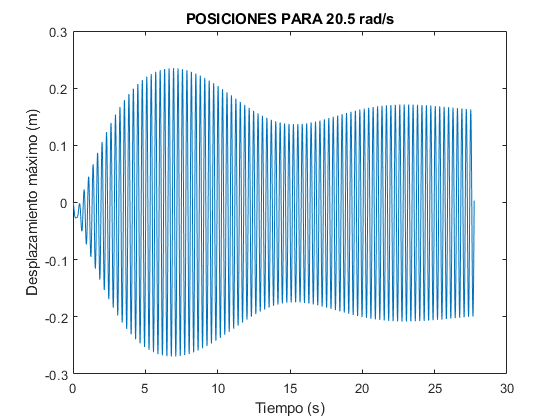


plot(vector_tiempo_20_5,posiciones_nodo_0_20_5(:,3))
title('POSICIONES PARA 20.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

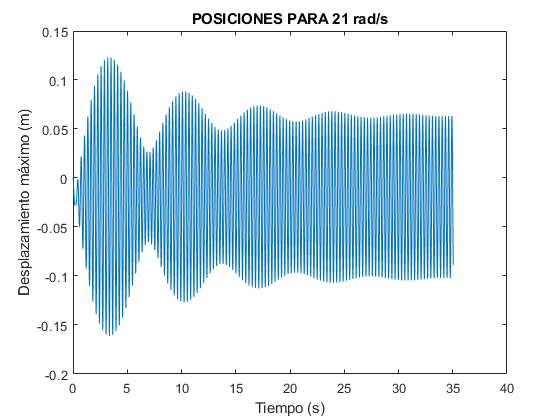


plot(vector_tiempo_21,posiciones_nodo_0_21(:,3))
title('POSICIONES PARA 21 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)') 

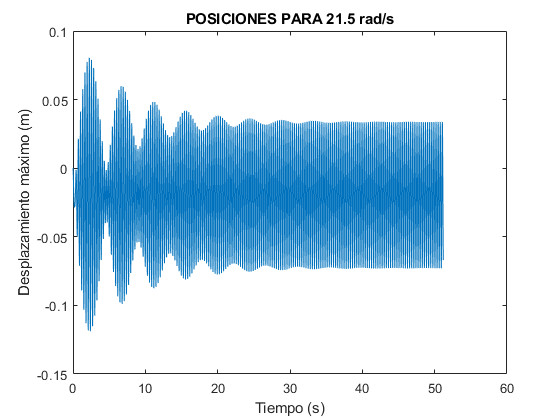


plot(vector_tiempo_21_5,posiciones_nodo_0_21_5(:,3))
title('POSICIONES PARA 21.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Desplazamiento máximo (m)')


% Realizamos las representación de las distintas energías para cada
% frecuencia estudiada
n=1

n = 1

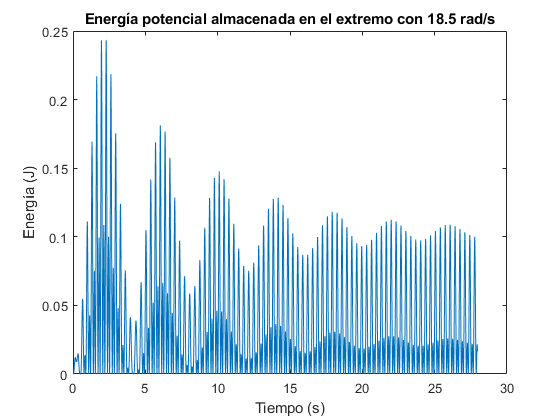

for i=1:length(posicion_nodo_0_dcha_split_18_5)
    % Calculamos la energía potencial
    Ep18_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_18_5(i,3))^2;
    if (vector_tiempo_18_5(i,1)>15.2)
        % Almacenamos los valores estacionarios
        Ep18_5_(i) = 2*18.4339*0.5*(posiciones_nodo_0_18_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_18_5,Ep18_5)
title('Energía potencial almacenada en el extremo con 18.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

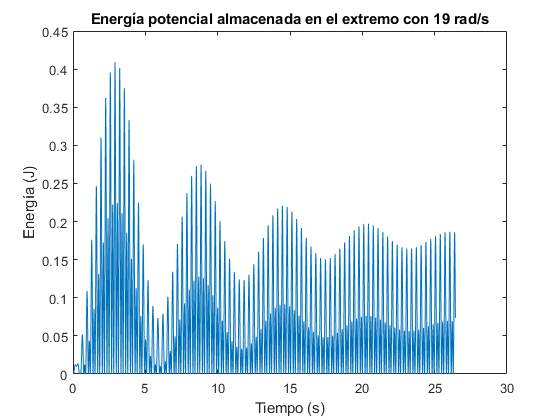

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_19)
    Ep19(i) = 2*18.4339*0.5*(posiciones_nodo_0_19(i,3))^2;
    if (vector_tiempo_19(i,1)>16.1)
        Ep19_(i) = 2*18.4339*0.5*(posiciones_nodo_0_19(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_19,Ep19)
title('Energía potencial almacenada en el extremo con 19 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

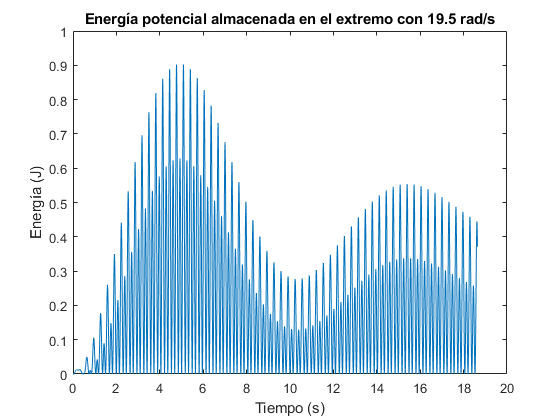

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_19_5)
    Ep19_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_19_5(i,3))^2;
    if (vector_tiempo_19_5(i,1)>8.3)
        Ep19_5_(i) = 2*18.4339*0.5*(posiciones_nodo_0_19_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_19_5,Ep19_5)
title('Energía potencial almacenada en el extremo con 19.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

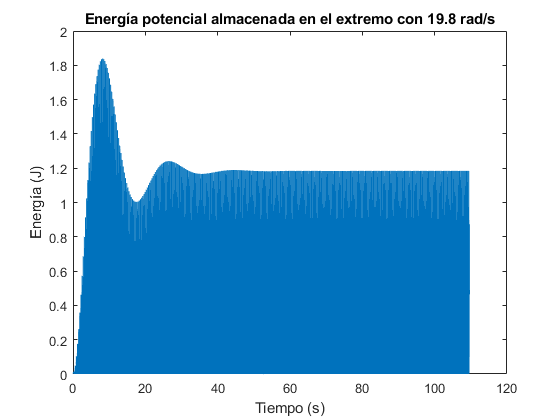

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_19_8)
    Ep19_8(i) = 2*18.4339*0.5*(posiciones_nodo_0_19_8(i,3))^2;
    if (vector_tiempo_19_8(i,1)>60)
        Ep19_8_(i) = 2*18.4339*0.5*(posiciones_nodo_0_19_8(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_19_8,Ep19_8)
title('Energía potencial almacenada en el extremo con 19.8 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

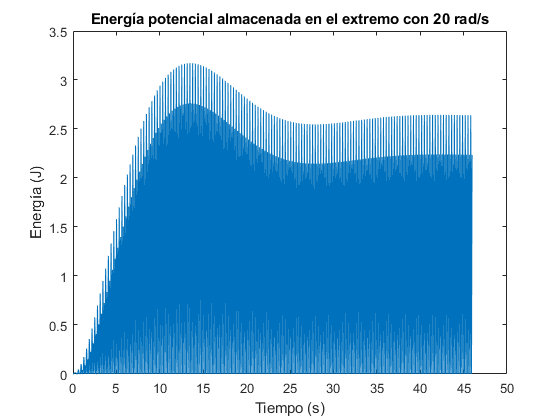

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_20)
    Ep20(i) = 2*18.4339*0.5*(posiciones_nodo_0_20(i,3))^2;
    if (vector_tiempo_20(i,1)>24)
        Ep20_(i) = 2*18.4339*0.5*(posiciones_nodo_0_20(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_20,Ep20)
title('Energía potencial almacenada en el extremo con 20 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

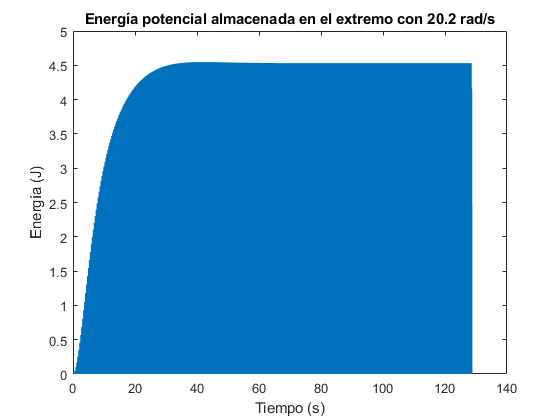

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_20_2)
    Ep20_2(i) = 2*18.4339*0.5*(posiciones_nodo_0_20_2(i,3))^2;
    if (vector_tiempo_20_2(i,1)>80)
        Ep20_2_(i) = 2*18.4339*0.5*(posiciones_nodo_0_20_2(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_20_2,Ep20_2)
title('Energía potencial almacenada en el extremo con 20.2 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

n=1

n = 1

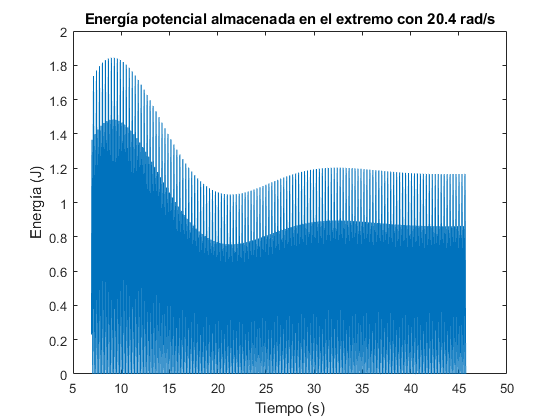

for i=1:length(posicion_nodo_0_dcha_split_20_4)
    Ep20_4(i) = 2*18.4339*0.5*(posiciones_nodo_0_20_4(i,3))^2;
    if (vector_tiempo_20_4(i,1)>17.5)
        Ep20_4_(i) = 2*18.4339*0.5*(posiciones_nodo_0_20_4(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_20_4,Ep20_4)
title('Energía potencial almacenada en el extremo con 20.4 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

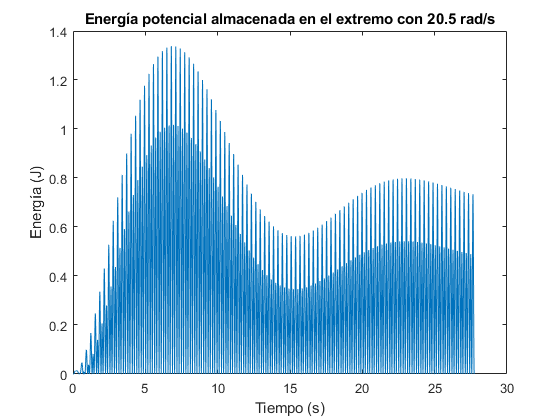

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_20_5)
    Ep20_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_20_5(i,3))^2;
    if (vector_tiempo_20_5(i,1)>11.5)
        Ep20_5_(i) = 2*18.4339*0.5*(posiciones_nodo_0_20_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_20_5,Ep20_5)
title('Energía potencial almacenada en el extremo con 20.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

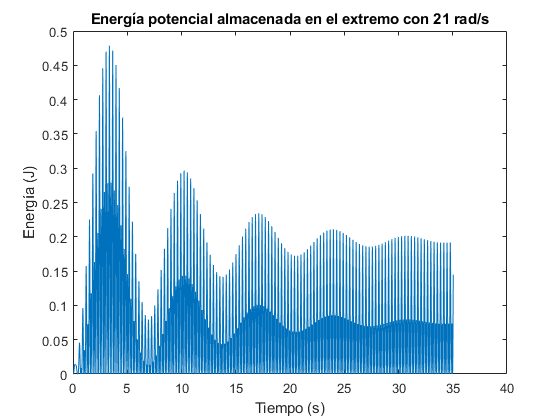

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_21)
    Ep21(i) = 2*18.4339*0.5*(posiciones_nodo_0_21(i,3))^2;
    if (vector_tiempo_21(i,1)>17.2)
        Ep21_(n) = 2*18.4339*0.5*(posiciones_nodo_0_21(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_21,Ep21)
title('Energía potencial almacenada en el extremo con 21 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

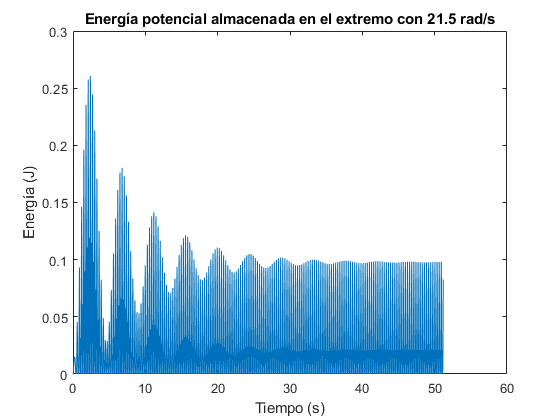

n = 1;
for i=1:length(posicion_nodo_0_dcha_split_21_5)
    Ep21_5(i) = 2*18.4339*0.5*(posiciones_nodo_0_21_5(i,3))^2;
    if (vector_tiempo_21_5(i,1)>40)
        Ep21_5_(n) = 2*18.4339*0.5*(posiciones_nodo_0_21_5(i,3))^2;
        n = n + 1;
    end
end
plot(vector_tiempo_21_5,Ep21_5)
title('Energía potencial almacenada en el extremo con 21.5 rad/s')
xlabel('Tiempo (s)')
ylabel('Energía (J)')

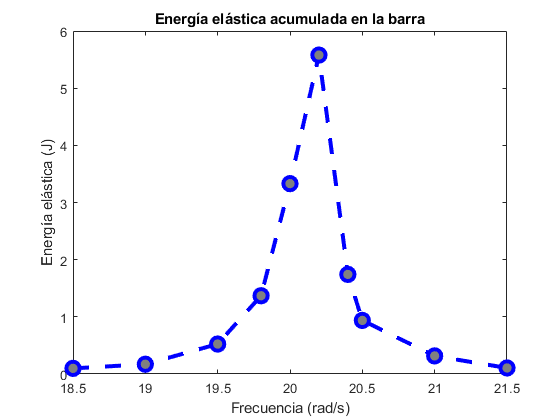

n = 1;

% Hallamos el valor de RMS
Ep18_5_rms = rms(Ep18_5_);
Ep19_rms = rms(Ep19_);
Ep19_5_rms = rms(Ep19_5_);
Ep19_8_rms = rms(Ep19_8_);
Ep20_rms = rms(Ep20_);
Ep20_2_rms = rms(Ep20_2_);
Ep20_4_rms = rms(Ep20_4_);
Ep20_5_rms = rms(Ep20_5_);
Ep21_rms = rms(Ep21_);
Ep21_5_rms = rms(Ep21_5_);

% Agrupamos los valores de energía potencial
Ep_rms = [Ep18_5_rms, Ep19_rms, Ep19_5_rms, Ep19_8_rms, Ep20_rms, Ep20_2_rms, Ep20_4_rms, Ep20_5_rms, Ep21_rms, Ep21_5_rms];

% Almacenamos los valores de frecuencias
omega = [18.5,19,19.5,19.8,20,20.2,20.4,20.5,21 21.5]';

% Aplicamos la reducción a 1 seg
T = 2*pi./omega;
scale_to_seg = 1./T;
Elastic_Energy = Ep_rms'.*scale_to_seg; % Energía usada en 1 seg

% Representamos la energía potencial escalada y lista para la comparación
plot(omega,Elastic_Energy,'--bo',...
    'LineWidth',3,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
title('Energía elástica acumulada en la barra')
xlabel('Frecuencia (rad/s)')
ylabel('Energía elástica (J)')